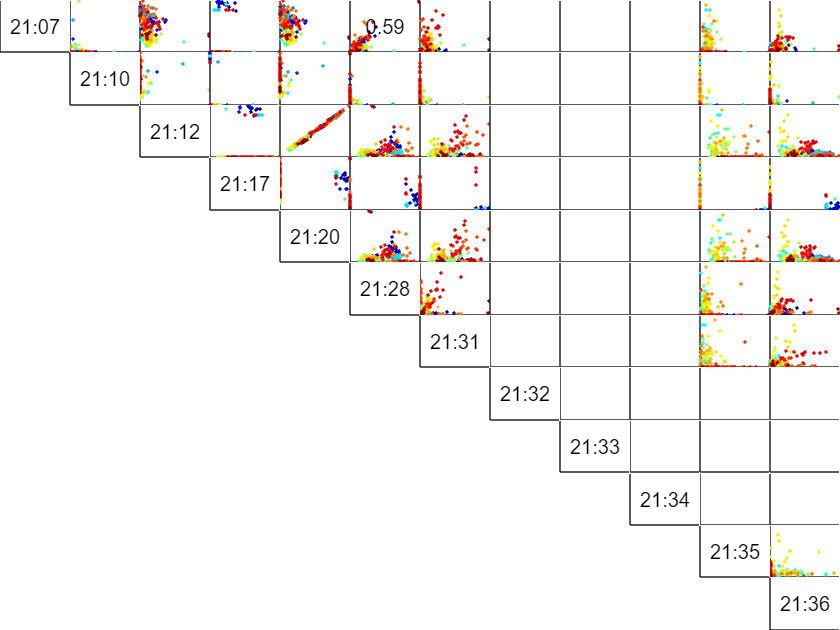

Features = DFD_FeatureTable_FreqDomain;
FeatureNames = featureNames_Freq;
SignalNames = signalNames_Freq;
lowerR2 = 0.2;
upperR2 = 0.8;
r2ReducedThreshold = 0.9;
selectedFeature = 1; % Band Power
saveFigures = true;
R2 = fnPlotSignalVsSignal(Features, lowerR2, upperR2, selectedFeature, FeatureNames, SignalNames, sensorNames); 

disp(num2str(R2, '%.2f  '));

0.00  0.00  0.06  0.04  0.08  0.59  0.03   NaN   NaN   NaN  0.00  0.02
0.00  0.00  0.00  0.00  0.00  0.01  0.00   NaN   NaN   NaN  0.00  0.00
0.00  0.00  0.00  0.01  0.99  0.00  0.00   NaN   NaN   NaN  0.13  0.10
0.00  0.00  0.00  0.00  0.01  0.10  0.00   NaN   NaN   NaN  0.03  0.00
0.00  0.00  0.00  0.00  0.00  0.00  0.00   NaN   NaN   NaN  0.13  0.10
0.00  0.00  0.00  0.00  0.00  0.00  0.05   NaN   NaN   NaN  0.00  0.02
0.00  0.00  0.00  0.00  0.00  0.00  0.00   NaN   NaN   NaN  0.00  0.17
0.00  0.00  0.00  0.00  0.00  0.00  0.00  0.00   NaN   NaN   NaN   NaN
0.00  0.00  0.00  0.00  0.00  0.00  0.00  0.00  0.00   NaN   NaN   NaN
0.00  0.00  0.00  0.00  0.00  0.00  0.00  0.00  0.00  0.00   NaN   NaN
0.00  0.00  0.00  0.00  0.00  0.00  0.00  0.00  0.00  0.00  0.00  0.00
0.00  0.00  0.00  0.00  0.00  0.00  0.00  0.00  0.00  0.00  0.00  1.00


selectedSignal = 1; % row number
selectedFeature = selectedFeature + 13;
[selectedSignalArray, selectedSignalData, numOfSelectedSignals] = fnSelectSignals(...
    selectedSignal, selectedFeature, featureArray, R2, upperR2, lowerR2, r2ReducedThreshold, true);

     1     6

     1     6



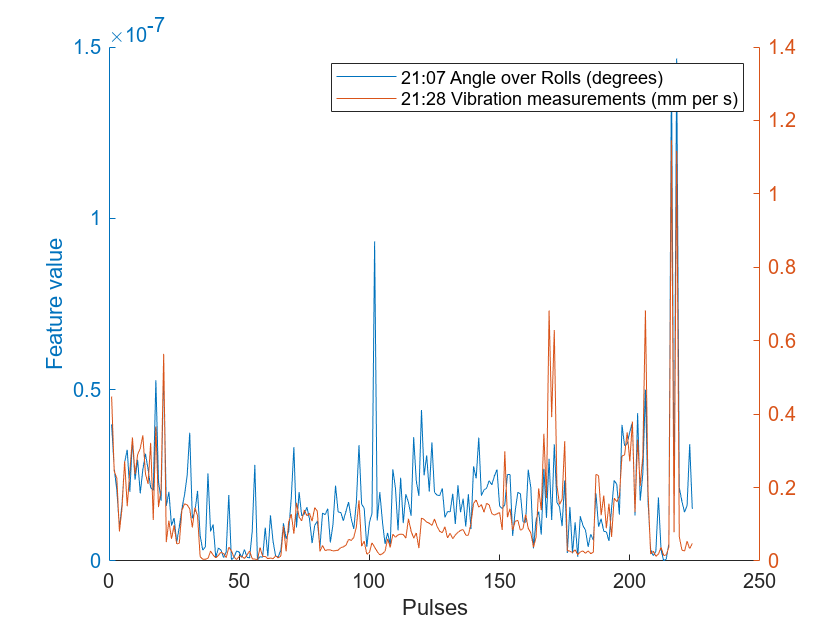

figure(); hold on;
FeatureNames_Combined(selectedFeature);%title(FeatureNames_Combined(selectedFeature));
xlabel("Pulses");
ylabel("Feature value");
secondaryAxisArrayIndex = [2];
for i = 1:numOfSelectedSignals
    if ismember(i, secondaryAxisArrayIndex)
        yyaxis right;
    else
        yyaxis left;
    end
    plot(selectedSignalData{i});
    leg{i} = char(sensorNames(selectedSignalArray(i)));
end
legend(leg);
if (saveFigures == true)
    filename = "..\Latex Document\figures\Models_Feature" + selectedFeature ...
        + "Signal" + selectedSignal;
    print(filename,'-depsc','-tiff');
end

txtTitle = "14 BandPower"

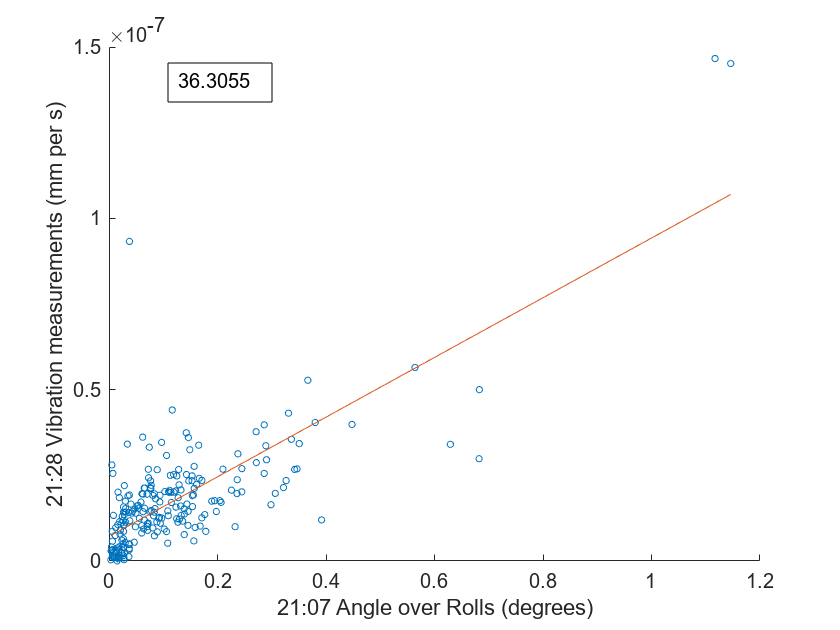

selectedSignalIdx = find(selectedSignalArray == selectedSignal);
linearModelNum = 1;
for index = 1 : numOfSelectedSignals
    if selectedSignalArray(index) ~= selectedSignal
        fnPlotModel(selectedSignalData{selectedSignalIdx}, ...
            selectedSignalData{index}, ...
            FeatureNames_Combined(selectedFeature), ...
            sensorNames(selectedSignalArray(index)), ...
            sensorNames(selectedSignal));
        if (saveFigures == true)
            filename = "..\Latex Document\figures\Models_Feature" + selectedFeature ...
                + "Signal" + selectedSignal ...
                + "_Linear" + linearModelNum;
            export_fig(filename, '-eps', '-depsc');
            linearModelNum = linearModelNum + 1;
        end
    end
end

multivariateModelNum = 1;
if numOfSelectedSignals > 2
    for index1 = 1 : numOfSelectedSignals
        for index2 = index1+1 : numOfSelectedSignals
            if selectedSignalArray(index1) ~= selectedSignal && selectedSignalArray(index2) ~= selectedSignal 
                %fprintf("%i %i %i", selectedSignalIdx, index1, index2);
                Y_est = fnPlotModel3D( ...
                    selectedSignalData{selectedSignalIdx}, ...
                    selectedSignalData{index1}, ...
                    selectedSignalData{index2}, ...
                    FeatureNames(selectedFeature), ...
                    sensorNames(selectedSignalArray(selectedSignalIdx)), ...
                    sensorNames(selectedSignalArray(index1)), ...
                    sensorNames(selectedSignalArray(index2)));

                if (saveFigures == true)
                    filename = "..\Latex Document\figures\Models_Feature" + selectedFeature ...
                        + "Signal" + selectedSignal ...
                        + "_Multivariate" + multivariateModelNum;
                    export_fig(filename, '-eps', '-depsc');
                    multivariateModelNum = multivariateModelNum + 1;
                end
            end
        end
    end
end